# Semantic ensemble analysis

Investigators often have specific visual concepts they want to operationalize, but sometimes one lacks the specific image-generation tools to do this. Here we leveraged convolutional neural networks to represent visual concepts that can be described semantically (e.g., "curvature," "faces"). The tactic is to use two image data stores that represent a contrast - for example, using images containing curved lines and images containing straight lines to capture the concept of "curvature", or using images containing monkey faces and images containing monkey bodies to capture the concept of "faces." By propagating each pair of image sets into a neural network, one can identify collections of hidden units that respond to the target category more than to the alternative category. These units represent a "semantic ensemble" that can be used to test separate image sets. 

This approach was inspired by the practice of fMRI-analysis localizer techniques, where one selects voxels using one dataset, testing the selected voxels with separately collected data sets. 

% add the necessary files to the path (this should be all that is required)
addpath(genpath(pwd))
addpath(genpath(fullfile(fileparts(pwd),'data')))
addpath(genpath(fullfile(fileparts(pwd),'utils')))


## Creating the ensemble

In this section, we declare the neural network and layer in which to identify the hidden units that will form the ensemble.

net = alexnet; % readily available in Matlab. Calling it for the first time will prompt a way to download it from Mathworks.
net_name = 'alexnet';
layers_all = {'relu1', 'relu2','relu3','relu4','relu5','relu6','relu7','fc8'} ;
iLayer = 6 ; 
t_layer = layers_all{iLayer} ;

% semantic hypothesis
all_hypotheses = {'curvature'};

myP_threshold = 0.0001; % threshold for selecting each unit

for iHypo = 1:length(all_hypotheses)

    selection_criterion = all_hypotheses{iHypo}

    % add more categories here
    switch selection_criterion
        case 'curvature'
            layers_to_test = layers_all{iLayer} ;
            path2Target = 'data\curved_gabors' ;
            path2Alternative  = 'data\straight_gabors' ;
            category = 'curvature' ;
    end

    dsTarget = imageDatastore(path2Target);
    dsAlternative =  imageDatastore(path2Alternative);

    auTarget = augmentedImageDatastore(net.Layers(1).InputSize,dsTarget,...
        'ColorPreprocessing','gray2rgb') ;
    auAlternative = augmentedImageDatastore(net.Layers(1).InputSize,dsAlternative,...
        'ColorPreprocessing','gray2rgb') ;

    % compute activations
    act_Target = activations(net,auTarget,t_layer,'OutputAs','channels');
    act_Alternative = activations(net,auAlternative,t_layer,'OutputAs','channels');
    
    % if using a convolutional layer, this code would have to be modified.
    act_Target1 = squeeze(act_Target)';
    act_Alternative1 = squeeze(act_Alternative)';

    p_values = nan(size(act_Target1,2),1);
    for iUnit = 1:size(act_Target1,2)
        p_values(iUnit) = ranksum(act_Target1(:,iUnit), act_Alternative1(:,iUnit),'tail','right' ) ; % right x > left
    end

    mean_Target = mean(act_Target1,1) ;
    mean_Alternative = mean(act_Alternative1,1) ;

    all_units = find( p_values < myP_threshold & mean_Target' > 1 ) ;

end

selection_criterion = 'curvature'

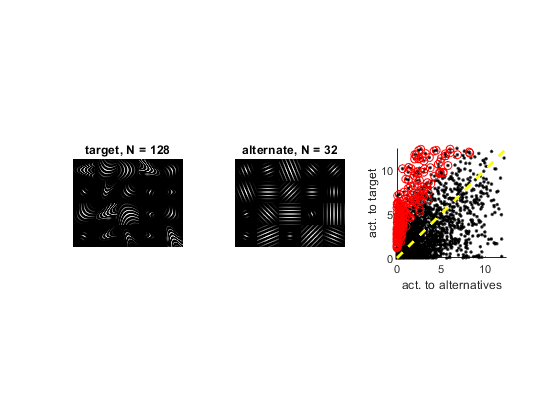


auTarget.reset;
auAlternative.reset;
imgsT = read(auTarget);
imgsP = read(auAlternative) ;

figure
tiledlayout(1,3);
rng(2)
npics = size(imgsT,1);
if npics > 20, areShown = randsample(npics,20); else, areShown = 1:npics; end
tmp_pics = table2array(imgsT);
nexttile; montage(tmp_pics(areShown)) ; title(sprintf('target, N = %d',npics));

npics = size(imgsP,1);
if npics > 20, areShown = randsample(npics,20); else, areShown = 1:npics; end
tmp_pics2 =table2array(imgsP);
nexttile; montage(tmp_pics2(areShown)) ; title(sprintf('alternate, N = %d',npics));

nexttile
plot(mean_Alternative,mean_Target,'k.');
hold on
plot(mean_Alternative(all_units),mean_Target(all_units),'ro');
axis tight square
box off

prctile_values = prctile([mean_Alternative,mean_Target],[0.01 99]);
h = fig_diag(prctile_values(1),prctile_values(2)); set(h,'color','y');
axis([prctile_values(1),prctile_values(2),prctile_values(1),prctile_values(2)]);
ylabel('act. to target');
xlabel('act. to alternatives');

Now you can input the separately collected input images and quantify the activations of the semantic ensemble (in red) to every test image.